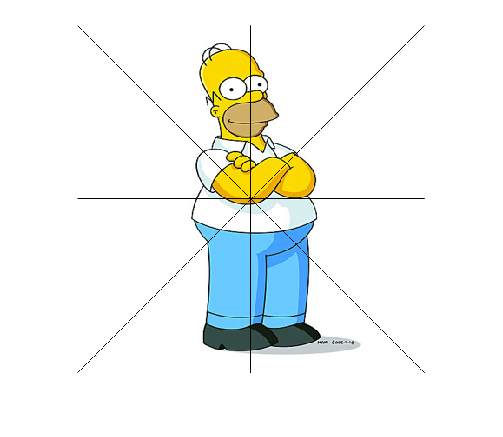

clear all;
bild = imread('bild2.jpg');
bild = imresize(bild, [400 400]);
bildW = wasser(bild);
imshow(bildW)

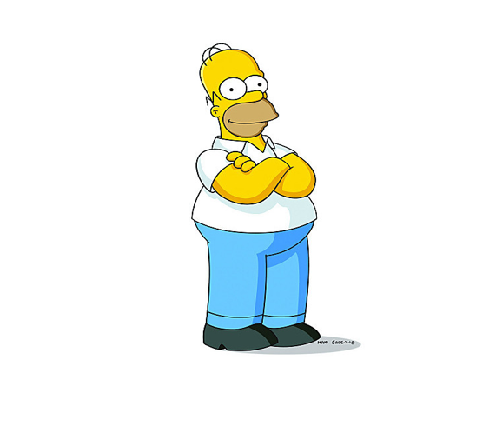

figure;
bildOhneWasserZeichen = wasserzeichenReomver(bildW, bild);
imshow(bildOhneWasserZeichen)

imwrite(bildW, ['wasserSimposn.jpg'], 'jpg', 'Quality', 80);


function [bildErg] = wasser(bild)
    [zeilen, spalten, ~] = size(bild);
    bildErg  = bild;
    for i = 1:zeilen
        bildErg(round(zeilen/2), i,:) = 0;
    end
    for i = 1:spalten
        bildErg(i, round(spalten/2),:) = 0;
    end
    for i = 1:zeilen
        bildErg(i, i, :) = 0; % Horizontal line
    end
    for i = 1:zeilen
        bildErg(i, zeilen-i+1, :) = 0; % Horizontal line
    end
    

end

function [bildOW] = wasserzeichenReomver(bildW, OrgBild)
    [zeilen, spalten, ~] = size(bildW);
    bildOW  = bildW;
    for i = 1:zeilen
        for j = 1:spalten
            if bildW(i,j,:) == 0
                bildOW(i,j,:) = OrgBild(i,j,:);
            end
        end
    end
end